## Question 1

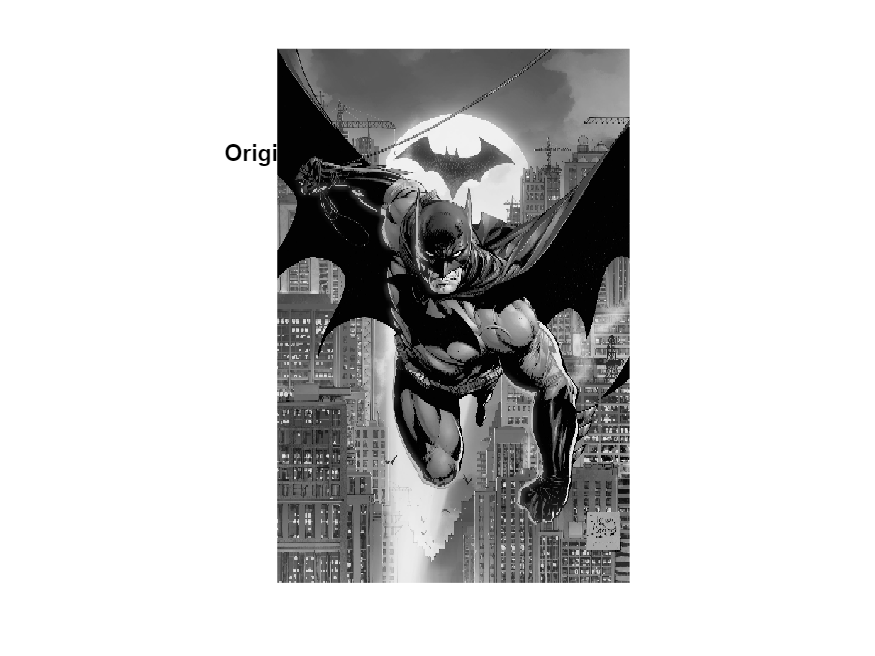

img = imread('Bat.jpg');
gray_img = rgb2gray(img);
figure, imshow(gray_img);
title('Original Grayscale Image');

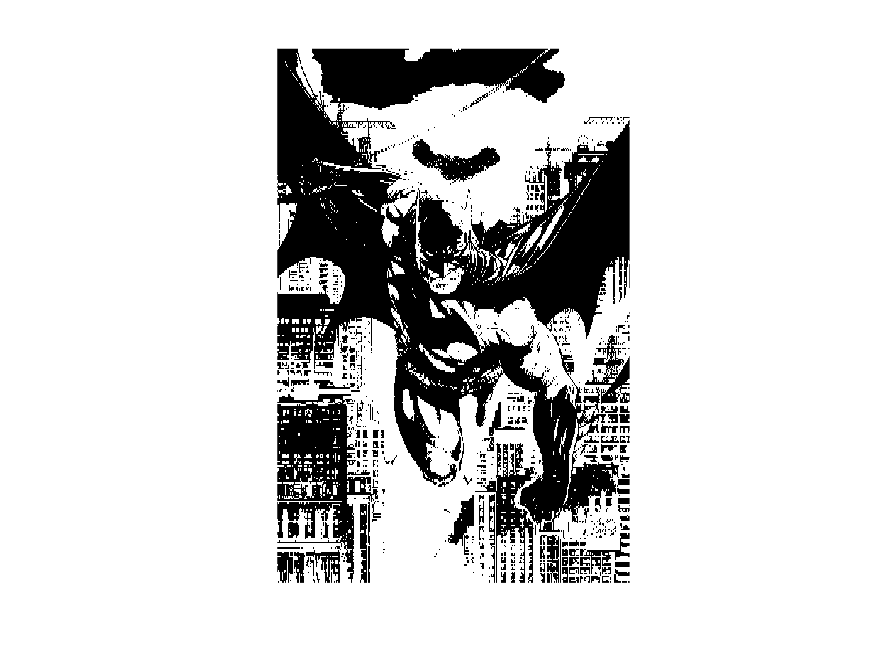

threshold_value = 100;
binary_mask = imbinarize(gray_img, threshold_value/255);
figure, imshow(binary_mask);
title('Binary Mask');

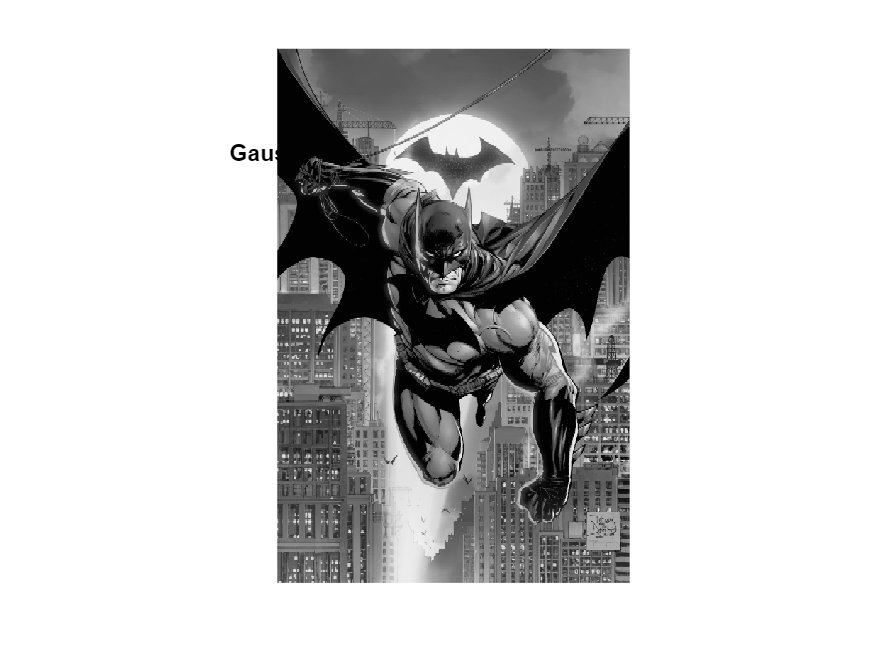

h_gaussian = fspecial('gaussian', [5,5], 2);
img_gaussian = imfilter(gray_img, h_gaussian);
figure, imshow(img_gaussian);
title('Gaussian Filtered Image');

disp('Histogram for Gaussian Filtered Image:');

Histogram for Gaussian Filtered Image:


disp(histcounts(img_gaussian));

       10853     1011795       51296       26301       17938       15555       14948       13242       11039       11248       10076       10237       10228        8234        7990        8503        8284        8212        7519        7356        8456        9017        8251        7462        7284        7268        7065        6950        6740        6824        7160        7345        7588        7824        7899        7793        7883        8287        9204        9701        9935        9874       10169       10025       10117       10110       10240       10431       10494       10942       11451       11835       11594       12006       12597       12964       13425       14215       14349       15134       16153       16236       17800       18092       19580       19969       24920       27861       27280       24157       25098       24347       25937       26355       27629       25945       26278       26647       28624       33801       31877       34295       35276    

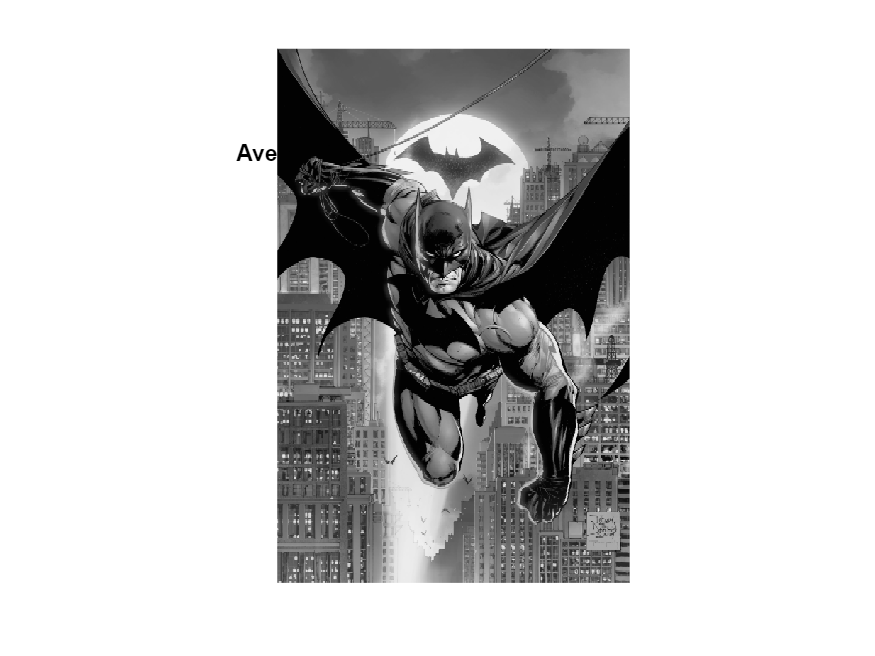

h_average = fspecial('average', [5,5]);
img_avg = imfilter(gray_img, h_average);
figure, imshow(img_avg);
title('Average Filtered Image');

disp('Histogram for Average Filtered Image:');

Histogram for Average Filtered Image:


disp(histcounts(img_avg));

        9519     1008839       50084       26133       17822       15484       14868       12960       10853       11203        9917       10318        9993        8410        8069        8528        8226        8168        7714        7483        8566        8917        8186        7570        7360        7360        7080        7021        7012        7006        7286        7290        7604        7911        7844        7859        8036        8404        9204        9851        9717        9807       10208       10033        9972        9977       10118       10423       10635       10859       11028       11406       11706       11964       12714       13008       13472       14185       14507       15363       16321       16212       17507       18031       19117       20225       24817       27629       26918       24266       24967       24658       25848       25719       27595       26450       26168       27018       29005       33893       32283       34140       35683    

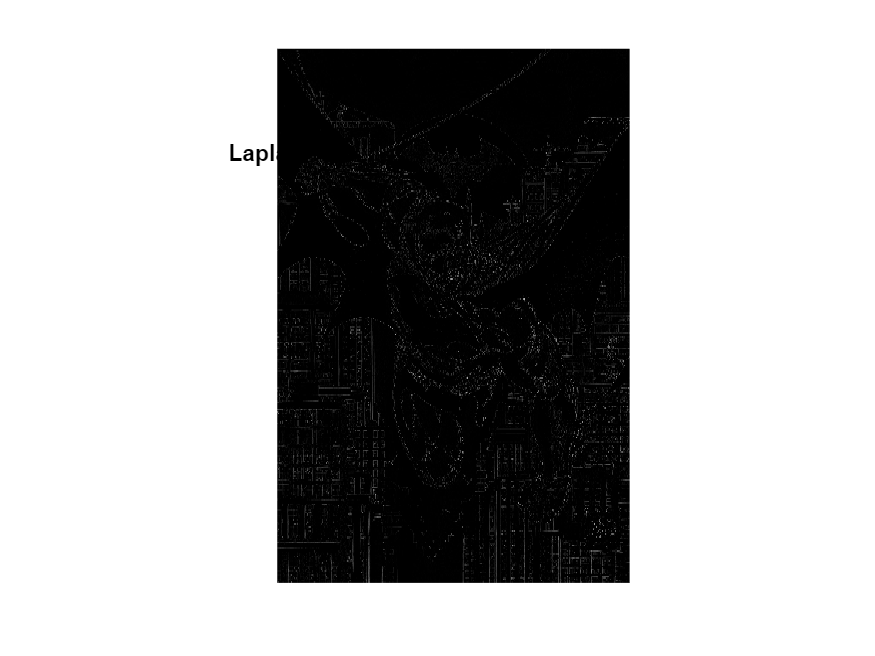

h_laplacian = fspecial('laplacian', 0.2);
img_laplacian = imfilter(gray_img, h_laplacian);
figure, imshow(img_laplacian, []);
title('Laplacian Filtered Image');

disp('Histogram for Laplacian Filtered Image:');

Histogram for Laplacian Filtered Image:


disp(histcounts(img_laplacian));

     4032366           0           0           0           0      456887           0           0           0           0      252209           0           0           0           0      138648           0           0           0           0      102998           0           0           0           0       84208           0           0           0           0       70424           0           0           0           0       59367           0           0           0           0       51637           0           0           0           0       44806           0           0           0           0       39828           0           0           0           0       35387           0           0           0           0       32423           0           0           0           0       29437           0           0           0           0       27794           0           0           0           0       25444           0           0           0           0       23522           0           0    

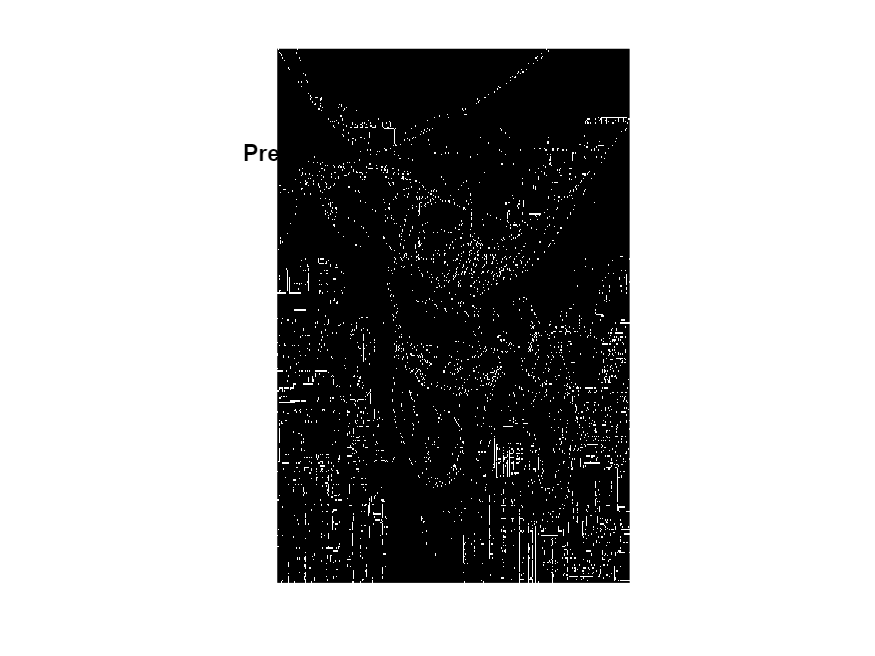

img_prewitt = edge(gray_img, 'prewitt');
figure, imshow(img_prewitt);
title('Prewitt Filtered Image');

disp('Histogram for Prewitt Filtered Image:');

Histogram for Prewitt Filtered Image:


disp(histcounts(img_prewitt));

     5766828      234944



disp('Explanation and Observations:');

Explanation and Observations:


disp('1. The original image is converted to grayscale to simplify the analysis.');

1. The original image is converted to grayscale to simplify the analysis.


disp('2. A binary mask is created using a threshold to isolate regions of interest.');

2. A binary mask is created using a threshold to isolate regions of interest.


disp('3. Gaussian and Average filters are applied to reduce noise and smooth the image.');

3. Gaussian and Average filters are applied to reduce noise and smooth the image.


disp('4. Laplacian and Prewitt filters are used to enhance and detect edges, respectively.');

4. Laplacian and Prewitt filters are used to enhance and detect edges, respectively.


disp('5. The effects of these filters are visualized and can be analyzed by comparing the output images and histograms.');

5. The effects of these filters are visualized and can be analyzed by comparing the output images and histograms.


disp('6. Histograms provide a quantitative view of the pixel intensity distribution after each filtering step, offering insights into the filter effects.');

6. Histograms provide a quantitative view of the pixel intensity distribution after each filtering step, offering insights into the filter effects.
